# **Integrales múltiples**

**En un problema de integración múltiple para una función de varias variables **$f(x_1,x_2,...,x_n)$, la integral se expresea de la forma $I=\int_{a_1}^{b_1}\int_{a_2}^{b_2}...\int_{a_n}^{b_n}f(x_1,x_2,...,x_n)dx_n...dx_2dx_1$. Donde los límite $a_i$ y $b_i$ corresponden a cada una de las variables $x_i$.

Si la funciones es una superficies en un espacio de tres dimensiones donde la función para una de las coordenadas es $z=f(x,y)$, la integral es de la forma $I=\int_{a}^{b}\int_{c}^{d}f(x,y)dydx$.

# **Ejemplo integración múltiple**

**Supongamos que la temperatura de una placa rectangular calentada está descrita por la siguiente función: **$T(x,y)=2xy+2x-x^2-2y^2+72$. **Si la placa tiene 8 metros de largo (dimensión x) y 6 metros de ancho (dimensión**** y), calcula la temperatura promedio.**

**Una evaluació directa del promedio estaría dada por la suma de cada uno de los puntos dividida entre el número de puntos, cuyo resultado seria aproximadamente 47.33. **

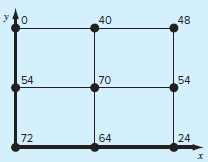

## **Analíticamente**

**El cálculo analítico de este temperatura estaría dado por **


$$\bar{T}=\frac{1}{área}\int_0^{ancho}\int_0^{largo}T(x,y)dxdy$$


sustituyendo los valores el valor analítico sería:


$$\bar{T}=\frac{1}{48}\int_0^{8}\int_0^{6}2xy+2x-x2-2y2+72dydx \approx58.66667$$


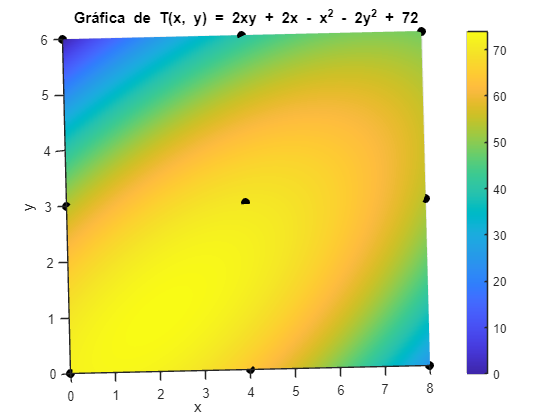

clc, clear, close all
% Definir la función T(x, y)
T = @(x, y) 2*x.*y + 2*x - x.^2 - 2*y.^2 + 72;

% Definir el rango de x e y
x = linspace(0, 8, 100);  % 100 puntos entre 0 y 8
y = linspace(0, 6, 100);  % 100 puntos entre 0 y 6

% Crear una malla de puntos (x, y)
[X, Y] = meshgrid(x, y);

% Evaluar la función T en la malla
Z = T(X, Y);

% Graficar la superficie en 3D
figure;  % Crear una nueva figura
surf(X, Y, Z);  % Graficar la superficie
xlabel('x');  % Etiqueta del eje x
ylabel('y');  % Etiqueta del eje y
zlabel('T(x, y)');  % Etiqueta del eje z
title('Gráfica de T(x, y) = 2xy + 2x - x^2 - 2y^2 + 72');  % Título de la gráfica
colorbar;  % Mostrar la barra de colores
shading interp;  % Interpolación de colores para suavizar la superficie
hold on;  % Mantener la gráfica actual para superponer los puntos

% Definir las coordenadas de los puntos a marcar
x_p = [0, 0, 0, 4, 4, 4, 8, 8, 8];  % Coordenadas x de los puntos
y_p = [0, 3, 6, 0, 3, 6, 0, 3, 6];  % Coordenadas y de los puntos
% Evaluar la función T en los puntos dados
z_p = T(x_p, y_p);
z_p_matriz = reshape(z_p, 3, 3);
% Graficar los puntos en 3D
plot3(x_p, y_p, z_p, 'k.', 'MarkerSize', 20);  % Puntos negros
hold off;  % Liberar la gráfica

## Numéricamente

### Regla del Trapecio

Ocupemos primero la regla del trapecio sobre el eje x y para cada valor de y. Recordando la regla del trapecio para una función $f(x)$ en un intervalo $[a,b]$ con un intervalo $h=b-a$ para un segmento de la función es $\int_a^bf(x,y)dx\approx h\frac{f(x_0,y_i)++f(x_1,y_i)}{2}$ donde $x_0=a$ y $x_1=b$. En el caso que tengamos $n$ segmentos la regla del trapecio compuesta es $\int_a^bf(x,y)dx\approx h\frac{f(x_0,y_i)+2\sum_{i=1}^{n-1}f(x_n,y_i)+f(x_n,y_i)}{2n}$. 

Para est caso, $h=8$ y el intervalor tiene tres puntos, es decir $n=2$, $f(x_0=0,y_2=6)=0$, $f(x_1=4,y_1=6)=40$ y $f(x_2=8,y_2=6)=48$ en el extremo de la placa a 6 metros del origen:


$$\int_a^bf(x,y)dx\approx (8-0)\frac{0+2(40)+48}{2\cdot 2}=256$$
 

Para los puntos a la mitad de la placa a 3 metrso del origen:


$$\int_a^bf(x,y)dx\approx (8-0)\frac{54+2(70)+54}{2\cdot 2}=496$$


Y para los puntos en el otro extremo de la placa:


$$\int_a^bf(x,y)dx\approx (8-0)\frac{72+2(64)+24}{2\cdot 2}=448$$


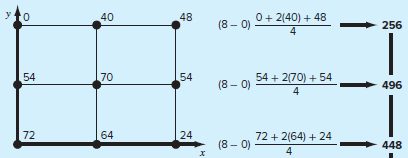

Estas integrales son cada una de las curvas debajo de cada segmento en la superficie. Ahora falta integrar estos promedios sobre el eje y para cada uno de los valores de x como:


$$\int_c^df(x,y)dy\approx (6-0)\frac{256+2(496)+448}{2\cdot 2}=2544$$
 

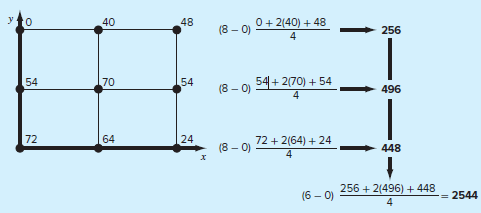

Este es el valor de la integral el cual falta dividirlo entre el área de la placa para obtener la temperatura promedio, es decir $\frac{2544}{48}=53$, el cual es un valor aproximado para el valor real de $56.887$.

% Valores de z=T(x,y) (z_p) obtenidos del programa anterior
z_p_matriz;

% Definir los límites del dominio
a = 0;  % Límite inferior en x
b = 8;  % Límite superior en x
c = 0;  % Límite inferior en y
d = 6;  % Límite superior en y

% Número de intervalos (puntos - 1)
n = 2;  % Número de intervalos en x / número de puntos menos el último
m = 2;  % Número de intervalos en y / número de puntos menos el último

% Tamaño de los pasos
hx = (b - a);  % Paso en x
hy = (d - c);  % Paso en y

% Aplicar la regla del trapecio en 2D
for j = 1 : m+1    % para los y
    % Sumar los términos en x para cada y fijo
    for i = 2 : n %para los x
        int_x = z_p_matriz(j, 1) + z_p_matriz(j, end);  % Términos en los extremos (primera y última columna)
        int_x = int_x + 2 * z_p_matriz(j, i);  % Términos interiores
    end
    % Aplicar la regla del trapecio en y
    INT_X(j) = int_x * hx / (2*n);  % Aplicar la regla del trapecio en x
end

for j = 2 : m
    int_y = INT_X(1) + INT_X(end);
    int_y = int_y + 2 * INT_X(j);
end

% Aplicar la regla del trapecio en y
I = int_y * hy / (2*m);

% Calcular el área del dominio
area = (b - a) * (d - c);

% Calcular el valor promedio
Temp_prom = I / area;

% Mostrar el resultado
fprintf('La temperatura promedio es: %.4f\n', Temp_prom);

La temperatura promedio es: 53.0000


Calcular la misma integral pero con la función *trapz *

% Valores de z_p (z_points) obtenidos del programa anterior
z_p_matriz;

% Definir los límites del dominio
a = 0;  % Límite inferior en x
b = 8;  % Límite superior en x
c = 0;  % Límite inferior en y
d = 6;  % Límite superior en y

% Definir los puntos en x & y
x = linspace(a, b, size(z_p_matriz, 2));  % Puntos en x
y = linspace(c, d, size(z_p_matriz, 1));  % Puntos en y

% Calcular la integral doble usando trapz
I = trapz(y, trapz(x, z_p_matriz, 2));

% Calcular el área del dominio
area = (b - a) * (d - c);

% Calcular el valor promedio
Temp_prom = I / area;

% Mostrar el resultado
fprintf('La temperatura promedio es: %.4f\n', Temp_prom);

La temperatura promedio es: 53.0000


### Regla de Simpsion 1/3

Recordando que para esta regla son necesarios 3 puntos y no 2 como en la regla del trapecio. La integral para ese segmento de la función donde se encuentren esos 3 puntos será $\int_a^bf(x,y)dx\approx h\frac{f(x_0,y_i)+4f(x_1,y_i)+f(x_2,y_i)}{6}$

El cálculo de la integral de Simpson 1/3 para $n$ segmentos en un intervalo total $h=b-a$ se escribe entonces como:


$$\int_a^bf(x,y)dx\approx h\frac{f(x_0,y_i)+4\sum_{k=impar}^{n-1}f(x_k,y_i)+2\sum_{k=par}^{n-2}f(x_k,y_i)+f(x_n,y_i)}{3\cdot n}$$


Realizando el mismo procedimiento primero sobre el eje $x$ para cada segmento en el punto $y_i$ tendríamos para el segmento sobre $y=6$:


$$\int_a^bf(x,y)dx\approx (8-0)\frac{0+4(40)+48}{6}=277.3333$$


Para el segmento a la mitad de la placa en $y=3$


$$\int_a^bf(x,y)dx\approx (8-0)\frac{54+4(70)+54}{6}=517.3333$$


Para el segmento en el extremo de la placa $y=0$


$$\int_a^bf(x,y)dx\approx (8-0)\frac{72+4(64)+24}{6}=469.3333
$$


Siguiendo con el mismo procedimeinto aplicamos ahora la regla de Simpson sobre los valores calculado sobre el eje $y$ como:


$$\int_a^bf(x,y)dx\approx (8-0)\frac{277.3333+4(517.3333)+469.3333}{6}=2815.9986$$


Y donde el la temperatura promedio es $\frac{2815.9986}{48}=58.6666$, valor que es mas aproximado al valor analítico.

% Valores de z_p (z_points) obtenidos del programa anterior
z_p_matriz;

% Definir los límites del dominio
a = 0;  % Límite inferior en x
b = 8;  % Límite superior en x
c = 0;  % Límite inferior en y
d = 6;  % Límite superior en y

% Número de intervalos (puntos - 1)
n = 2;  % Número de intervalos en x / número de puntos menos el último
m = 2;  % Número de intervalos en y / número de puntos menos el último

% Tamaño de los pasos
hx = (b - a);  % Paso en x
hy = (d - c);  % Paso en y

% Aplicar la regla del trapecio en 2D
for j = 1 : m+1    % para los y
    % Sumar los términos en x para cada y fijo
    % sum_x = z_p(j, 1) + z_p(j, end);  % Términos en los extremos (primera y última columna)
    for i = 2 : n %para los x
        int_x = z_p_matriz(j, 1) + z_p_matriz(j, end);  % Términos en los extremos (primera y última columna)
        int_x = int_x + 4 * z_p_matriz(j, i);  % Términos interiores
    end
    % Aplicar la regla del trapecio en y
    INT_X(j) = int_x * hx / (3*n);  % Aplicar la regla del trapecio en x
end

for j = 2 : m
    int_y = INT_X(1) + INT_X(end);
    int_y = int_y + 4 * INT_X(j);
end

% Aplicar la regla del trapecio en y
I = int_y * hy / (3*m);

% Calcular el área del dominio
area = (b - a) * (d - c);

% Calcular el valor promedio
Temp_prom = I / area;

% Mostrar el resultado
fprintf('La temperatura promedio es: %.4f\n', Temp_prom);

La temperatura promedio es: 58.6667
